%% Simulation of linear system of monocopter with flaps 
% clc
% clear all
% close all
 
% load ka_flap.mat
% load ka_flap_NDI.mat

%% Parameters
J = 3.2284E-6; % moment of inertia of the rotor 3.2284E-6
b = 3.5077E-6; % motor viscous friction constant 3.5077E-6
K = 0.0274; % electromotive force constant, motor torque constant 0.0274 
R = 4; % electric resistance 
L = 2.75E-6; % electric inductance  
Jxx = 100; % symmetrical so most of it is abt x so therefore Jxx = 0.0005713669 if tracking was ideal
Jxx_1st = 110; 
Jxx_2nd = 130; 
Jzz = 0.0005982825;
plot_variable = 1;
pitch = 25.61; % deg
pitch = abs(pitch);
% (bod pitch * ka * motor rpm) contributes to lift force for disk torque due to total pitch generated
ka = 1; % based on sam values wud be 5.413E-3, but this probably 
ka = ka*plot_variable; % x1, x2, x3, x4, x5...all the way to x13, default is x 10
rps = -40.9663;
rps_squared = rps^2;
cl = 0.5; % naca 0006, includes flap and wing est of 0.5
cd = 0.052; % naca 0006
g = 9.81;
rho = 1.225;
radius = 0.26;
chord_length = 0.12;
mass = 0.053; % added servo and rods 0.053
altitude = 1.25;
coam = -1; % conservation of angular momentum so reversed

% for x:
% 1.5 - 0.5
% 1.25 - 0.5
% 1.0 - 0.5

% for y:
% 2.0 -  0.85
% 1.75 - 0.9 
% 1.5 - 0.95
% 1.25 - 1.05
% 1.0 - 1.2

torque_w_mass = radius*((cl*pitch*ka*rps_squared*rho*chord_length*(radius^3))/(6));
drag_rotation = (cd*pitch*ka*rps_squared*rho*chord_length*(radius^3))/(6*mass);
moving_axis = 'x';

rotational_drag_coeff = 0.001;

if moving_axis == 'x'
    com = 1/(rotational_drag_coeff*(g + drag_rotation)); % omega abt y is positive (roll) linear acc x
elseif moving_axis == 'y'
    com = 1/(-(g + drag_rotation)*rotational_drag_coeff); % omega abt x is negative (pitch) linear acc y
end

linesize = 3;
Fontsize = 10;
scaling = 1;

t = 0:0.01:5;
% monocopter precession is like a speed booster lol
if moving_axis == 'x'   
    u3 = scaling*(1/3*(sin((2.2*t)-(pi/2)))); % omega abt y, linear acc x
    u = scaling*(sin((2.2*t)-(pi/2))); % omega abt y, linear acc x  
elseif moving_axis == 'y'   
    u3 = scaling*(1/3*sin((2.5*t)-(pi))); % omega abt x, linear acc y
    u = scaling*(sin((2.5*t)-(pi))); % omega abt x, linear acc y
end


%% servo and angular acceleration feedback
omega_dot = torque_w_mass/Jxx;
omega_dot_1st = torque_w_mass/Jxx_1st;
omega_dot_2nd = torque_w_mass/Jxx_2nd;

s = tf('s');
servo = K/(s*((J*s+b)*(L*s+R)+K^2)); % includes the integral to positional angle alrd
% H_servo = 3.54; % w feedback
H_servo = 0.0; % wo feedback (currently in place for the flaps ver wj is building)
H_omega_dot_tf = 1; % feedback activated  
stf = servo/(1+(servo*H_servo));
% stf = feedback(servo,1);
% isstable(stf)
% pole(stf)
%omega_dot_tf = stf; % ndi

response_delay = 0.02; % Monocopter tpp angular acceleration delay
%omega_dot = (1/omega_dot)*stf*omega_dot*response_delay;
omega_dot = stf*omega_dot;
omega_dot_1st = stf*omega_dot_1st;
omega_dot_2nd = stf*omega_dot_2nd;

% isstable(omega_dot_tf)
% pole(omega_dot_tf)

[omega_dot_controller,info] = pidtune(omega_dot,'P');
omega_dot_tf_c = feedback(omega_dot_controller*omega_dot,1);
omega_dot_tf = feedback(omega_dot,1);

%omega_dot_tf_1st = feedback(omega_dot_controller*omega_dot_1st,1);
%omega_dot_tf_2nd = feedback(omega_dot_controller*omega_dot_2nd,1);

omega_dot_tf_1st = feedback(omega_dot_1st,1);
omega_dot_tf_2nd = feedback(omega_dot_2nd,1);

% omega_dot_tf = feedback(omega_dot,1); % implement feedback for tf which is servo to become servo/(1+(servo*H)
% isstable(omega_dot_tf)
% pole(omega_dot_tf)

% to simulate step input of a single servo angle
st = 0:0.001:0.30;
% Config = RespConfig('Amplitude',3.5+0.04);
% step(stf, st, Config) % step function here is in the form of a servo angle 
% ylabel('Position, \theta (radians)')
% title('Response to a Step Reference (servo)')

%% for omega_dot_tf
Config = RespConfig('Amplitude',0.5); 
step_pure_flap = step(omega_dot_tf, st, Config) 

step_pure_flap =          0
    0.0000
    0.0000
    0.0001
    0.0002
    0.0003
    0.0004
    0.0005
    0.0007
    0.0009


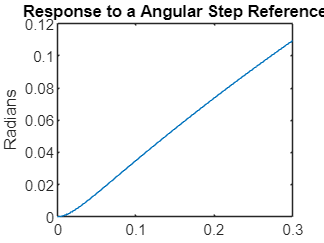

plot(st,step_pure_flap)
ylabel('Radians')
title('Response to a Angular Step Reference')

%% to simulate disturbance step input

% [omega_dot_pi,info_d] = pidtune(stf*torque_w_mass,'PID')
% disturbance_torque_tf = 1/(Jxx+(omega_dot_controller*H_omega_dot_tf*Jxx*stf)); % w feedback

disturbance_torque_tf = 1/(Jxx*(1+(omega_dot_controller*H_omega_dot_tf*stf)));

%disturbance_torque_tf = ((s^2)*com)/(((s^2)*com)+(H_omega_dot_tf*omega_dot)) % w feedback
% disturbance_torque_tf = 1/Jxx % wo feedback
dt = 0:0.001:0.3;
isstable(disturbance_torque_tf)

ans = logical
   1


pole(disturbance_torque_tf)

ans = 1.0e+06 *

  -1.4545 + 0.0000i
  -0.0000 + 0.0003i
  -0.0000 - 0.0003i


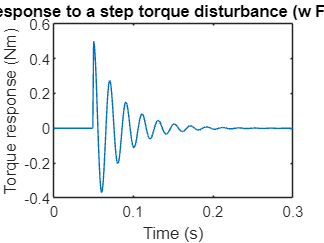

Config = RespConfig('Amplitude',0.5,'Delay',0.05);
disturbance = step(disturbance_torque_tf, dt, Config); % step function here is in the form of a servo angle 
disturbance_pure_flap = disturbance/(1/Jxx);
plot(dt,disturbance_pure_flap)
% ylabel('$\frac{acceleration output}{acceleration due to disturbance}$','Interpreter','latex','FontSize',Fontsize)
ylabel('Torque response (Nm)','FontSize',Fontsize)
xlabel('Time (s)','FontSize',Fontsize)
title('Response to a step torque disturbance (w Flaps)')

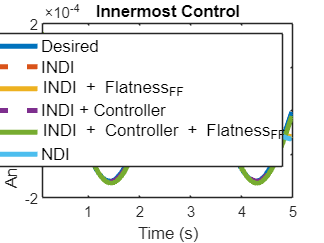

% inner raterate control loop (INDI)

% isstable(omega_dot_tf)
% pole(omega_dot)
u3_dot = diff(u3);
u3_dotdot = transpose(diff(u3_dot));
flatness_component = u3_dotdot/com;

indi = lsim(omega_dot_tf,u3_dotdot,t(1,1:499)); % INDI
indi_c = lsim(omega_dot_tf_c,u3_dotdot,t(1,1:499)); % INDI w controller
indi_1st = lsim(omega_dot_tf_1st,u3_dotdot,t(1,1:499)); % INDI
indi_2nd = lsim(omega_dot_tf_2nd,u3_dotdot,t(1,1:499)); % INDI
ndi = lsim(omega_dot,u3_dotdot,t(1,1:499)); % NDI very big
plot (t(1,1:499),u3_dotdot,'LineWidth',linesize)
hold on
plot(t(1,1:499),indi,'lineStyle','--','LineWidth',linesize)
plot(t(1,1:499),indi+flatness_component,'LineWidth',linesize)
plot(t(1,1:499),indi_c,'lineStyle','--','LineWidth',linesize)
plot(t(1,1:499),indi_c+flatness_component,'LineWidth',linesize)
%plot(t,indi_1st,'LineWidth',linesize)
%plot(t,indi_2nd,'lineStyle','--','LineWidth',linesize)
plot(t(1,1:499),ndi,'LineWidth',linesize) % NDI can be tested
hold off
xlim([0.1 5])

ylabel('Angular Acceleration','FontSize',Fontsize)
xlabel('Time (s)','FontSize',Fontsize)
title('Innermost Control','FontSize',Fontsize)
legend('Desired','INDI','INDI + Flatness_FF','INDI + Controller','INDI + Controller + Flatness_FF','NDI','FontSize',Fontsize)

%legend('Desired','INDI','INDI + Flatness_FF','NDI','FontSize',Fontsize)
%legend('Desired','INDI','INDI_1st','INDI_2nd','NDI','FontSize',Fontsize)

Error_indi = u3_dotdot - indi;
Error_indi_flatness = u3_dotdot - (indi+flatness_component);
Error_indi_c = u3_dotdot - indi_c;
Error_indi_flatness_c = u3_dotdot - (indi_c+flatness_component);

Error_indi = (Error_indi.^2);
Error_indi_flatness = (Error_indi_flatness.^2)/499;
Error_indi_c = (Error_indi_c.^2)/499;
Error_indi_flatness_c = (Error_indi_flatness_c.^2)/499;

rmse_indi = sqrt(sum(Error_indi)/499)

rmse_indi = 1.0438e-04

rmse_indi_flatness = sqrt(sum(Error_indi_flatness)/499)

rmse_indi_flatness = 4.5398e-06

rmse_indi_c = sqrt(sum(Error_indi_c)/499)

rmse_indi_c = 5.9454e-07

rmse_indi_flatness_c = sqrt(sum(Error_indi_flatness_c)/499)

rmse_indi_flatness_c = 6.0162e-07

% inner rate control loop (INDI)

%omega = (s+D)*com*omega_dot_tf*(1/(s^2))*1/com; % jerk only
omega = omega_dot_tf*(1/(s)); % jerk only
[omega_controller,omega_info] = pidtune(omega,'P')
omega_tf_ndi = omega_dot*(1/(s)); % jerk and snap NDI
omega_tf = feedback(omega_controller*omega,1); % jerk and snap INDI
% isstable(omega_tf)
% pole(omega_tf)


rate_indi = lsim(omega_tf,u3,t);
rate_ndi = lsim(omega_tf_ndi,u3,t);
plot (t,u3,'LineWidth',linesize)
hold on
plot(t,rate_indi,'lineStyle',':','LineWidth',linesize)
%plot(t,rate_ndi,'lineStyle','--','LineWidth',linesize)
%plot(t,jerk+snap+gyro_y_flap,'LineWidth',linesize) % linear acc y
%plot(t,jerk+snap+gyro_x_flap,'LineWidth',linesize) % linear acc x
hold off
xlim([0.1 5])

ylabel('Angular Velocity','FontSize',Fontsize)
xlabel('Time (s)','FontSize',Fontsize)
title('Inner-rate Control','FontSize',Fontsize)
legend('Desired','rate(INDI)','rate(NDI)','FontSize',Fontsize)


% outer angle control loop (INDI)
angle = omega_tf*(1/(s));
[angle_controller,angle_info] = pidtune(angle,'P')
angle_tf = feedback(angle_controller*angle,1);
angle_tf_ndi = omega_tf_ndi*(1/(s)); % wo close loop for bod rates and raterate
%[angle_controller_ndi,angle_ndi_info] = pidtune(angle_ndi,'PID');
%angle_tf_ndi = feedback(angle_controller_ndi*angle_ndi,1);


% isstable(angle_tf)
% pole(angle_tf)

quat_3 = lsim(angle_tf,u3,t);
quat_ndi_3 = lsim(angle_tf_ndi,u3,t);
plot (t,u3,'LineWidth',linesize)
hold on
plot(t,quat_3,'lineStyle','--','LineWidth',linesize)
plot(t,quat_ndi_3,'lineStyle',':','LineWidth',linesize)
hold off
%ylim([-0.4 0.4])

ylabel('Angle','FontSize',Fontsize)
xlabel('Time (s)','FontSize',Fontsize)
title('Outer-angle Control (mimicking precession curve)','FontSize',Fontsize)
legend('Desired','angle(INDI)','angle(NDI)','FontSize',Fontsize)

% quat u1
quat = lsim(angle_tf,u,t);
quat_ndi = lsim(angle_tf_ndi,u,t);
plot (t,u,'LineWidth',linesize)
hold on
plot(t,quat_ndi,'lineStyle',':','LineWidth',linesize)
plot(t,quat,'lineStyle','--','LineWidth',linesize)
hold off

ylabel('Acceleration output (m/s^2)','FontSize',Fontsize)
xlabel('Time (s)','FontSize',Fontsize)
title('Flap response to a reference with orientation angle tracking u','FontSize',Fontsize)
legend('desired','orientation angle (NDI)','orientation angle (INDI)','FontSize',Fontsize)


%% compute precession
% compute when linear acc x
if moving_axis == 'x' 
    t_t = transpose(t);
    dydx_quat_y = gradient(quat(:)) ./ gradient(t_t(:));
    dydx_jerk_y = gradient(jerk+snap_indi+quat_3(:)) ./ gradient(t_t(:));

    dydx_quat_y = (dydx_quat_y*Jxx)/(rps*Jzz);
    dydx_jerk_y = (dydx_jerk_y*Jxx)/(rps*Jzz);
 
    precession_radius_y_jerk = abs(altitude*tan((jerk+snap_indi+quat_3)*com));
    precession_radius_y_quat = abs(altitude*tan((quat)*com));

    gyro_y_flap_quat = dydx_quat_y.*precession_radius_y_quat;
    gyro_y_flap = dydx_jerk_y.*precession_radius_y_jerk;
    
    % plot(t,gyro_y_flap_quat,'lineStyle',':','LineWidth',linesize) 
    % hold on
    % plot (t,gyro_y_flap,'lineStyle','--','LineWidth',linesize)
    % hold off
    % legend('(angle(wo snap + jerk))(INDI)','(angle + jerk + snap(INDI))(INDI)','FontSize',Fontsize)
    % xlim([0.1 5])

    plot(t,u,'lineStyle',':','LineWidth',linesize) 
    hold on
    plot (t,dydx_jerk_y,'lineStyle','--','LineWidth',linesize)
    hold off
    legend('desired','(angle + jerk + snap(INDI))(INDI)','FontSize',Fontsize)
    xlim([0 5])

% compute when linear acc y
elseif moving_axis == 'y' % negative one added to sync w the derivatives obtained from test_aux in exp_flat, scaled it through the other axis' signal
    t_t = transpose(t);
    dydx_quat_x = gradient(quat(:)) ./ gradient(t_t(:));
    dydx_jerk_x = gradient(jerk+snap_indi+quat_3(:)) ./ gradient(t_t(:));

    dydx_quat_x = -1*(dydx_quat_x*Jxx)/(rps*Jzz);
    dydx_jerk_x = -1*(dydx_jerk_x*Jxx)/(rps*Jzz);
 
    precession_radius_x_jerk = abs(altitude*tan((jerk+snap_indi+quat_3)*com));
    precession_radius_x_quat = abs(altitude*tan((quat)*com));

    gyro_x_flap_quat = dydx_quat_x.*precession_radius_x_quat;
    gyro_x_flap = dydx_jerk_x.*precession_radius_x_jerk;
    
    % plot(t,gyro_x_flap_quat,'lineStyle',':','LineWidth',linesize) 
    % hold on
    % plot (t,gyro_x_flap,'lineStyle','--','LineWidth',linesize)
    % hold off
    % legend('(angle(wo snap + jerk))(INDI)','(angle + jerk + snap(INDI))(INDI)','FontSize',Fontsize)
    % xlim([0.1 5])

    % plot(t,u,'lineStyle',':','LineWidth',linesize) 
    % hold on
    % plot (t,dydx_jerk_x,'lineStyle','--','LineWidth',linesize)
    % hold off
    % legend('desired','(angle + jerk + snap(INDI))(INDI)','FontSize',Fontsize)
    % xlim([0 5])
end

% all together w gyro, 
% for linear acc x, starting pt leads by pi/2, so contributor linear y (pitch) one lags behind by pi/2, in derivatives section somehow its accounted for alrd lol
% for linear acc y, starting pt leads by pi/2, so contributor linear x (roll) one lags behind by pi/2, in derivatives section somehow its accounted for alrd lol 
if moving_axis == 'x'
    plot (t,u,'LineWidth',linesize)
    hold on
    plot(t,quat+(coam*gyro_x_flap_quat),'lineStyle',':','LineWidth',linesize) % linear acc x  
    plot(t,jerk+snap_indi+quat_3+(coam*gyro_x_flap),'lineStyle','--','LineWidth',linesize) % linear acc x
    hold off
    % flap_x = jerk+snap_indi+quat_3+(coam*gyro_x_flap);
    xlim([0.07 5]) % linear acc x
      
    ylabel('Acceleration output (m/s^2)','FontSize',Fontsize)
    xlabel('Time (s)','FontSize',Fontsize)
    %xticklabels({'0.5','1','1.5','2','2.5','3','3.5','4','4.5','5'})
    % in the pitch, you will finally understand why i needed to invert the input to make it go ccw instead of its current cw due to precession
    title('Flap response to a reference w precession contributed from pitch (disk roll, moving along world x axis)','FontSize',Fontsize)
    legend('desired','(angle + gyro (wo snap + jerk))(INDI)','(angle + jerk + snap + gyro)(INDI)','FontSize',Fontsize)

elseif moving_axis == 'y' 
    plot (t,u,'LineWidth',linesize)
    hold on   
    plot(t,quat+(coam*gyro_y_flap_quat),'lineStyle',':','LineWidth',linesize) % linear acc y
    plot(t,jerk+snap_indi+quat_3+(coam*gyro_y_flap),'lineStyle','--','LineWidth',linesize) % linear acc y
    hold off
    % flap_y = jerk+snap_indi+quat_3+(coam*gyro_y_flap);
    xlim([0.07 5]) % linear acc y
    
    ylabel('Acceleration output (m/s^2)','FontSize',Fontsize)
    xlabel('Time (s)','FontSize',Fontsize)
    % xticklabels({'0.25','0.5','1','1.5','2','2.5','3','3.5','4'})
    % in the pitch, you will finally understand why i needed to invert the input to make it go ccw instead of its current cw due to precession
    title('Flap response to a reference w precession contributed from roll (disk pitch, moving along world y axis)','FontSize',Fontsize)
    legend('desired','(angle + gyro (wo snap + jerk))(INDI)','(angle + jerk + snap + gyro)(INDI)','FontSize',Fontsize)
end

% all together - no gyro
plot (t,u,'LineWidth',linesize)
hold on
plot(t,quat,'lineStyle',':','LineWidth',linesize) 
plot(t,jerk_ndi+snap_indi+quat_ndi_3,'lineStyle','--','LineWidth',linesize)
plot(t,jerk+snap_indi+quat_3,'lineStyle','--','LineWidth',linesize) 
hold off


if moving_axis == 'x'
    ylabel('Acceleration output (m/s^2)','FontSize',Fontsize)
    xlabel('Time (s)','FontSize',Fontsize)
    title('Flap response to a reference (disk roll, moving along world x axis)','FontSize',Fontsize)
    legend('desired','(angle(wo snap + jerk))(INDI)','(angle + jerk + snap(INDI))(NDI)','(angle + jerk + snap(INDI))(INDI)','FontSize',Fontsize)
    flap_x = jerk+snap_indi+quat_3;
    xlim([0.07 5])


elseif moving_axis == 'y'
    ylabel('Acceleration output (m/s^2)','FontSize',Fontsize)
    xlabel('Time (s)','FontSize',Fontsize)
    title('Flap response to a reference (disk pitch, moving along world y axis)','FontSize',Fontsize)
    legend('desired','(angle(wo snap + jerk))(INDI)','(angle + jerk + snap(INDI))(NDI)','(angle + jerk + snap(INDI))(INDI)','FontSize',Fontsize)    
    flap_y = jerk+snap_indi+quat_3;
    xlim([0.07 5])

end

count = size(t);
count = count(1,2);
%zero(count,1);

total_jerk_ndi = jerk_ndi+snap_indi+quat_ndi_3;
total_jerk_indi = jerk+snap_indi+quat_3;
rmse_quat_indi = 0.0;
rmse_jerk_ndi = 0.0;
rmse_jerk_indi = 0.0;
start = 0;

for n = 1+start:count
    rmse_quat_indi = rmse_quat_indi + (u(1,n) - quat(n,1))^2; 
    rmse_jerk_indi = rmse_jerk_indi + (u(1,n) - total_jerk_indi(n,1))^2; 
    rmse_jerk_ndi = rmse_jerk_ndi + (u(1,n) - total_jerk_ndi(n,1))^2; 
end


rmse_quat_indi 
rmse_jerk_indi
rmse_jerk_ndi 

% 50-50 x y
% 0.7761 0.0677
% 0.6835 0.1209
% 36.8002 75.9019

% rmse_quat_indi = sqrt(rmse_quat_indi/(count-start))
% rmse_jerk_indi = sqrt(rmse_jerk_indi/(count-start))
% rmse_jerk_ndi = sqrt(rmse_jerk_ndi/(count-start))

e_rmse_quat_indi_flap = sqrt((3.1044 + 0.2707)/(count-start))
e_rmse_jerk_indi_flap = sqrt((2.7339 + 0.4837)/(count-start))
e_rmse_jerk_ndi_flap = sqrt((147.2008 + 303.6075)/(count-start))


%jerk_scaling_factor_x = abs(mean(transpose((jerk+snap+quat_3)./gyro_y_flap))); % linear acc x
%jerk_scaling_factor_y = mean(transpose((jerk+snap+quat_3)./gyro_x_flap)); % linear acc y
 

%ka_flap_values = zeros(501,10);
%ka_flap_values(:,plot_variable) = jerk+snap+gyro_y_flap;


% plot (t,u,'LineWidth',linesize)
% hold on
% for i = 1:10
%     plot(t,ka_flap_values(:,i),'LineWidth',linesize)
% end    
% hold off
% ylabel('Response','FontSize',Fontsize)
% xlabel('Time(seconds)','FontSize',Fontsize)
% title('Responses to different ka values (INDI)','FontSize',Fontsize)
% legend('desired','x1','x2','x3','x4','x5','x6','x7','x8','x9','x10') 

%ka_flap_values_NDI = zeros(501,10);
%ka_flap_values_NDI(:,plot_variable) = jerk_ndi+snap;

% plot (t,u,'LineWidth',linesize)
% hold on
% for i = 1:10
%     plot(t,ka_flap_values_NDI(:,i),'LineWidth',linesize)
% end    
% hold off
% ylabel('Response','FontSize',Fontsize)
% xlabel('Time(seconds)','FontSize',Fontsize)
% title('Responses to different ka values (NDI)','FontSize',Fontsize)
% legend('desired','x1','x2','x3','x4','x5','x6','x7','x8','x9','x10') 






%% compute precession (old method)
% compute when linear acc x
% if moving_axis == 'x' % negative one added to sync w the derivatives obtained from test_aux in exp_flat 
%     precession_jerk_snap_gyro_y_flap = 1*(((s+D)*com*omega_dot_tf*s*Jxx)+((s^2)*com*omega_dot*s*Jxx))/(Jzz*rps);
%     precession_quat_3_gyro_y_flap = 1*((com*omega_dot_tf*s*Jxx))/(Jzz*rps);
%     precession_quat_gyro_y_flap = 1*((com*omega_dot_tf*s*Jxx))/(Jzz*rps);
%     precession_jerk_snap_gyro_y_flap = lsim(precession_jerk_snap_gyro_y_flap,jerk_scaling_factor_x.*(2/3*sin((2.5*t)-(pi))),t); % linear acc y
%     precession_quat_3_gyro_y_flap = lsim(precession_quat_3_gyro_y_flap,jerk_scaling_factor_x.*(1/3*sin((2.5*t)-(pi))),t);
%     precession_quat_gyro_y_flap = lsim(precession_quat_gyro_y_flap,jerk_scaling_factor_x.*(sin((2.5*t)-(pi))),t);
% 
%     precession_radius_y_jerk = abs(altitude*tan((jerk+snap_indi+quat_3)*com));
%     precession_radius_y_quat = abs(altitude*tan((quat)*com));
% 
%     gyro_y_flap = precession_jerk_snap_gyro_y_flap + precession_quat_3_gyro_y_flap;
%     gyro_y_flap_quat = precession_quat_gyro_y_flap;
% 
%     gyro_y_flap = gyro_y_flap.*precession_radius_y_jerk;
%     gyro_y_flap_quat = gyro_y_flap_quat.*precession_radius_y_quat;
% 
% 
%     % gyro_y_flap = (((jerk+snap+quat_3)*radius*Jxx))/(Jzz*rps); % add this to acc_y
%     % gyro_y_flap_quat = (((quat)*radius*Jxx))/(Jzz*rps); % add this to acc_y
% 
% % compute when linear acc y
% elseif moving_axis == 'y' % negative one added to sync w the derivatives obtained from test_aux in exp_flat, scaled it through the other axis' signal
%     precession_jerk_snap_gyro_x_flap = -1*(((s+D)*com*omega_dot_tf*s*Jxx)+((s^2)*com*omega_dot*s*Jxx))/(Jzz*rps)
%     precession_quat_3_gyro_x_flap = -1*((com*omega_dot_tf*s*Jxx))/(Jzz*rps);
%     precession_quat_gyro_x_flap = -1*((com*omega_dot_tf*s*Jxx))/(Jzz*rps);
%     precession_jerk_snap_gyro_x_flap = lsim(precession_jerk_snap_gyro_x_flap,jerk_scaling_factor_y.*(2*1/3*(sin((2.2*t)-(pi/2)))),t); % linear acc y
%     precession_quat_3_gyro_x_flap = lsim(precession_quat_3_gyro_x_flap,jerk_scaling_factor_y.*(1/3*(sin((2.2*t)-(pi/2)))),t);
%     precession_quat_gyro_x_flap = lsim(precession_quat_gyro_x_flap,jerk_scaling_factor_y.*((sin((2.2*t)-(pi/2)))),t);
% 
%     precession_radius_x_jerk = abs(altitude*tan((jerk+snap_indi+quat_3)*com));
%     precession_radius_x_quat = abs(altitude*tan((quat)*com));
% 
%     gyro_x_flap = precession_jerk_snap_gyro_x_flap + precession_quat_3_gyro_x_flap;
%     gyro_x_flap_quat = precession_quat_gyro_x_flap;
% 
%     gyro_x_flap = gyro_x_flap.*precession_radius_x_jerk;
%     gyro_x_flap_quat = gyro_x_flap_quat.*precession_radius_x_quat;
% 
%     % plot (t, 2/3*(sin((2.2*t)-(pi/2))),'LineWidth',linesize)
%     % hold on
%     plot(t, gyro_x_flap,'lineStyle','--','LineWidth',linesize) % linear acc x
%     % hold off
%     ylabel('Acceleration output (m/s^2)','FontSize',Fontsize)
%     xlabel('Time (s)','FontSize',Fontsize)
%     % in the pitch, you will finally understand why i needed to invert the input to make it go ccw instead of its current cw due to precession
%     title('Gyro produced along linear y','FontSize',Fontsize)
% 
%     xlim([0.20 5])
%     % gyro_x_flap  = (-1*((jerk+snap+quat_3)*radius*Jxx))/(Jzz*rps); % add this to acc_x
%     % gyro_x_flap_quat  = (-1*((quat)*radius*Jxx))/(Jzz*rps); % add this to acc_x
% 
% end